syms flugel schrob snor
N = 24; % aantal rad plekken

n0 = 8; %niks winnen
n1 = 4; %1 prijs is geen prijs
n2 = 2;
n3 = 1; %op 13 en 17
n4 = 1; %e.g. 2 hoofdprijsen die op 22 en 5 komen te staan

%mogelijke uitkomsten
p0 = 0; 
p1 = 1;
p2 = 2;
p3 = 3;
p4 = 6;

k0 = n0 / N * 100; %kans op niks
k1 = n1 * 2 / N * 100; %kans op 1e prijs
k2 = n2 * 2 / N * 100; %2e prijs
k3 = n3 * 2 / N * 100; %3e prijs
k4 = n4 * 2 / N * 100; %4e prijs

cell2table({
    0 n0 p0 k0;
    1 n1*2 p1 k1;
    2 n2*2 p2 k2;
    3 n3*2 p3 k3;
    4 n4*2 p4 k3;
},'VariableNames',{'Prijs nummer', 'aantal', 'hoeveel uitdelen', 'kans'})

ans = 5×4 table
    Prijs nummer    aantal    hoeveel uitdelen     kans 
    ____________    ______    ________________    ______

         0            8              0            33.333
         1            8              1            33.333
         2            4              2            16.667
         3            2              3            8.3333
         4            2              6            8.3333



prijzen = zeros(n0,1) + p0;

prijzen = [prijzen; zeros(n1,1) + p1 * flugel]; %1 flugel is geen flugel = opnieuw draaien
prijzen = [prijzen; zeros(n2,1) + p2 * flugel]; %2 flugel
prijzen = [prijzen; zeros(n4,1) + p3 * flugel]; %4 flugel
prijzen = [prijzen; zeros(n8,1) + p4 * flugel]; %8 flugel

prijzen = [prijzen; zeros(n1,1) + p1 * schrob]; %1 schrob is geen schrob = opnieuw draaien
prijzen = [prijzen; zeros(n2,1) + p2 * schrob]; %2 schrob
prijzen = [prijzen; zeros(n4,1) + p3 * schrob]; %4 schrob
prijzen = [prijzen; zeros(n8,1) + p4 * schrob]; %8 schrob

length(prijzen) %moet gelijk aan 24 zijn

ans = 24

schrob = 31.91*1.21/44 %schrob prijs

schrob = 0.8775

flugel = 79.95*1.21/120 %flugel prijs

flugel = 0.8062

round(sum(subs(prijzen))/length(prijzen),3) %verwachte uitkomst

$$ans = 1.193$$

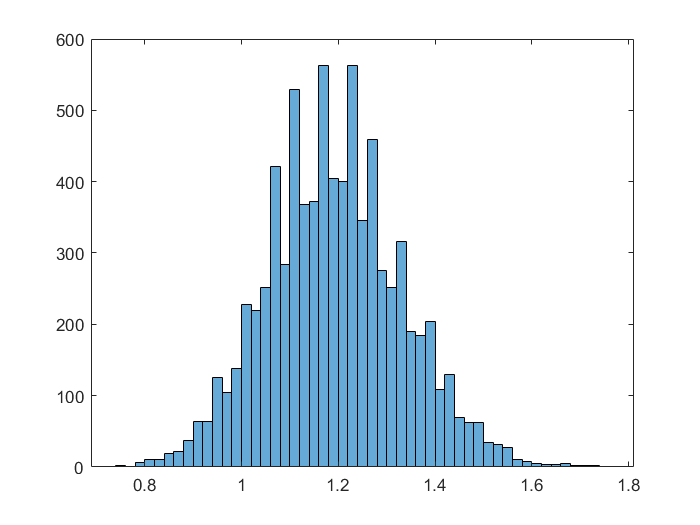

t = 8000; %hoeveel runs
N = 100; % hoevaak we het radje draaien
n0 = 8; %niks winnen
n1 = 4; %1 prijs is geen prijs
n2 = 2;
n3 = 1; %op 13 en 17
n4 = 1; %e.g. 2 hoofdprijsen die op 22 en 5 komen te staan
uitkomsten = zeros(t,1);

for j = 1 : t
    gem = 0; %lopende gemiddelde
    for i = 1 : N
        k = randi([1 24]);
        if k <= n0
            gem = gem + p0;
        elseif k <= n0 + n1*2
            gem = gem + p1;
        elseif k <= n0 + n1*2 + n2*2
            gem = gem + p2;
        elseif k <= n0 + n1*2 + n2*2 + n3*2
            gem = gem + p3;
        else 
            gem = gem + p4;
        end 
    end
    uitkomsten(j) = subs((gem/N) * (flugel + schrob)/2);
end

histogram(uitkomsten)


prijs0 = 0.6;
prijs1 = 2;
stap = 0.01;
N = length(uitkomsten);
prijzen = [prijs0:stap:prijs1]

prijzen =     0.6000    0.6100    0.6200    0.6300    0.6400    0.6500    0.6600    0.6700    0.6800    0.6900    0.7000    0.7100    0.7200    0.7300    0.7400    0.7500    0.7600    0.7700    0.7800    0.7900    0.8000    0.8100    0.8200    0.8300    0.8400    0.8500    0.8600    0.8700    0.8800    0.8900    0.9000    0.9100    0.9200    0.9300    0.9400    0.9500    0.9600    0.9700    0.9800    0.9900    1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900


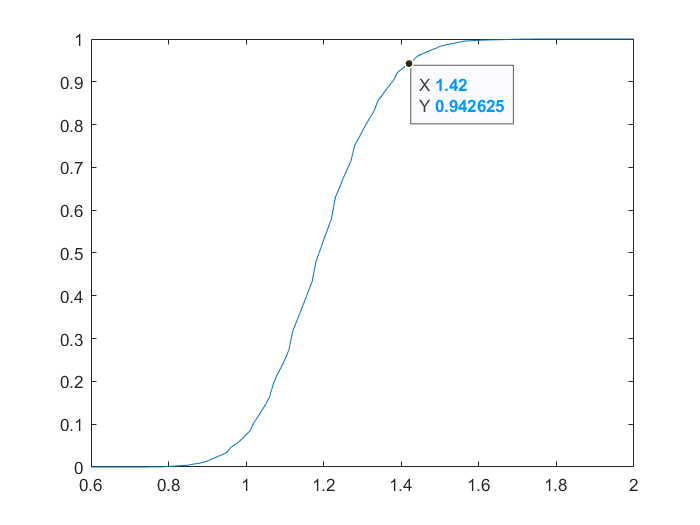

prijskans = zeros(length(prijzen),1);
for i = 1: length(prijzen)
    prijs = prijzen(i);
    prijskans(i) = length(nonzeros(uitkomsten(uitkomsten <= prijs)))/N;
end

plot(prijzen,prijskans)